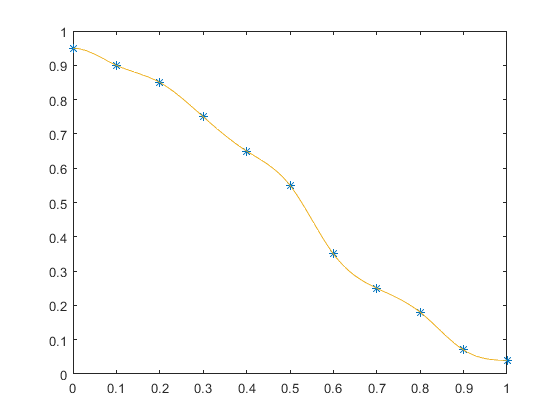

clear all;
t = linspace(0,1)';
x = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1]; 
f = [0.95 0.9 0.85 0.75 0.65 0.55 0.35 0.25 0.18 0.07 0.04];

c = CubicSpline(x,f,0);
rez = evalSpline(x,c,t);
fileID = fopen('score.txt','w');
[n,~] = size(rez);
for i = 1:n
    fprintf(fileID,'%d;%f\n',i,rez(i,1));
end
plot(x,f,'*',t,[rez,rez])